# Sync the data between IMU and MC system

## Purpose of file

- Sync the time between the IMU measurements and the MC measurements, that is, estimate the time-shift. 

- FInd the coarse and fine rotation between the twos.

- The time shift is estimated by estimating the angular velocities from the rotation matrices from the MC systems and compare with the angular velocities by the gyroscopes. If they are not aligned, one should compare the norm of the angular velocities, but the coarse alignment was sufficient to get the rotation around the x-axis. The the x component is only compared. Then time shift IMU x-component of omega and sum the squared differences. 

- A fine alignment is also performed by comparing the direction of gravity. This is not so important since this misalignment will be incorporated into the $R$ matrix in the filter. We will not compare rotation matrices only positions.

## Load Data


% Estimate bias from stationary phase.
% FIG_SIZE = [0,0,800*1.5,500*1.5]

normalize_norm_v = @(x) x ./ norm_time(x);


### Load MC data

serie = 2;
exp = 1;

% Load MC data 
% Load MC data 
pathScript = fileparts(matlab.desktop.editor.getActiveFilename)

pathScript = '/home/hakcar/phd/Array-INS-2/code/experiments/liu/serie-2/exp1'



file_mc  =sprintf("imu-%d-000%d.mat", serie, exp);
load(fullfile(pathScript,"raw_data","mc",file_mc));

% Load the data 
newStr = sprintf("imu_%d_000%d", serie, exp);
data_mc = eval(newStr);

### Load IMU data

data_IMU = load(fullfile(pathScript,"raw_data","imu","data_same_frame.mat"));

## Prepare data

N_sens = size(data_IMU.inertial_data_double_rot,1)

N_sens = 192

inds_tot = reshape(1:N_sens,6,[]);
N_imu = size(inds_tot,2);
inds_acc = reshape(inds_tot(1:3,:),[],1);
inds_gyro = reshape(inds_tot(4:6,:),[],1);
data_IMU.gyro = deg2rad(data_IMU.inertial_data_double_rot(inds_gyro,:));
data_IMU.acc = data_IMU.inertial_data_double_rot(inds_acc,:);
data_IMU.time = data_IMU.time_stamp_corr - data_IMU.time_stamp_corr(1);
data_IMU.acc

ans =    -0.4405   -0.4645   -0.4788   -0.4453   -0.4310   -0.4501   -0.4693   -0.4693   -0.4310   -0.4453   -0.5267   -0.4597   -0.3687   -0.4645   -0.4597   -0.4357   -0.4693   -0.4693   -0.4836   -0.4597   -0.5028   -0.4836   -0.4693   -0.3926   -0.4166   -0.4310   -0.4645   -0.4166   -0.3926   -0.4070   -0.4693   -0.4262   -0.3926   -0.4357   -0.4884   -0.4022   -0.4788   -0.4836   -0.4836   -0.4310   -0.4501   -0.4310   -0.4357   -0.4357   -0.4357   -0.4741   -0.4453   -0.4262   -0.4166   -0.4310
   -0.1341   -0.1389   -0.1389   -0.1628   -0.2203   -0.0958   -0.1437   -0.1149   -0.1772   -0.1389   -0.2251   -0.1341   -0.1484   -0.1676   -0.1437   -0.1628   -0.1532   -0.1197   -0.1437   -0.1197   -0.0670   -0.1532   -0.1772   -0.1293   -0.1867   -0.1437   -0.0958   -0.2203   -0.1341   -0.1628   -0.1437   -0.1197   -0.2059   -0.1867   -0.1580   -0.1772   -0.1389   -0.1389   -0.1101   -0.2155   -0.1389   -0.1101   -0.1484   -0.1676   -0.1293   -0.1484   -0.1149   -0.1676   -0.2059   

R_imu2rig_coarse = [ 
    0   -1  0;
    -1  0  0;
    0  0 -1];

data_IMU_mc_frame = struct;
R_imu2rig_coarse

R_imu2rig_coarse =      0    -1     0
    -1     0     0
     0     0    -1


% First around z, then around y, then around x
eul2rotm(deg2rad([-90 0 180]))

ans =     0.0000   -1.0000   -0.0000
   -1.0000   -0.0000   -0.0000
         0    0.0000   -1.0000


R_imu2rig_coarse - eul2rotm(deg2rad([-90 0 180]))

ans = 	1.0e+-15 *

   -0.0612         0    0.1225
         0    0.0612    0.0000
         0   -0.1225         0


data_IMU_mc_frame.r0 = R_imu2rig_coarse*data_IMU.r0

data_IMU_mc_frame = struct with fields:
    r0: [3×32 double]


data_IMU.r0*1e3

ans =    -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500
    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500    3.1500    3.1500    9.4500    9.4500   -9.4500   -9.4500   -3.1500   -3.1500
    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000


data_IMU_mc_frame.r0*1e3

ans =    -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500   -3.1500   -3.1500   -9.4500   -9.4500    9.4500    9.4500    3.1500    3.1500
    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    9.4500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500    3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -3.1500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500   -9.4500
   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000   -1.0000    1.0000


R_imu2rig_coarse_tot = kron(eye(N_imu), R_imu2rig_coarse);
data_IMU_mc_frame.acc = R_imu2rig_coarse_tot*data_IMU.acc;
data_IMU_mc_frame.gyro = R_imu2rig_coarse_tot*data_IMU.gyro;
data_IMU_mc_frame.time = data_IMU.time;
data_IMU_mc_frame.Ts = data_IMU.Ts;
data_IMU_mc_frame.Fs = data_IMU.Fs;
data_IMU_mc_frame.mean_gyro = triad_mean(data_IMU_mc_frame.gyro);
data_IMU_mc_frame.mean_acc = triad_mean(data_IMU_mc_frame.acc);
% assert(all(data_R0_t_shift.R_imu2rig_coarse == eul2rotm(deg2rad([-90 0 180])), "all"))

#### Check MC Data

There are some missing samples in the MC data

p_mm = squeeze(data_mc.RigidBodies.Positions); % Positions in mm

bad_points = logical(any(isnan(p_mm)));
good_points = ~bad_points;

p_tot = p_mm/1000;
p = p_tot(:,good_points);
t_tot = ((data_mc.StartFrame:data_mc.Frames) - 1)/data_mc.FrameRate;
t = t_tot(good_points);


## Check Time 

#### Missing samples in the MC system

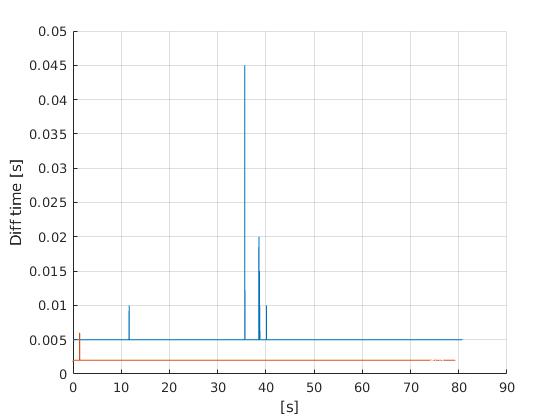

figure(); hold on
plot(t(1:end-1), diff(t), 'DisplayName',"Motion Capture")
plot(data_IMU.time(1:end-1),diff(data_IMU.time),'DisplayName',"IMU")
xlabel("[s]")
ylabel("Diff time [s]")
grid on

Some missing samples.

#### 3D plot of trajectory MC system

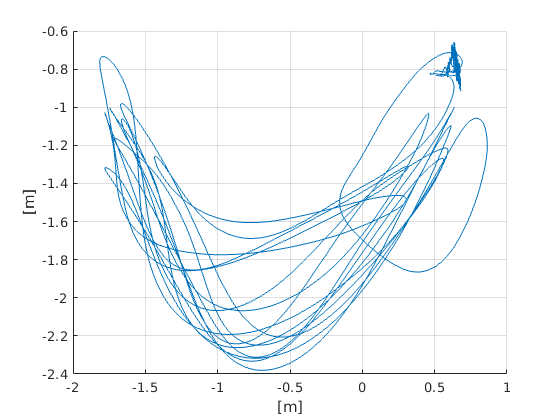

figure(); clf; hold on
plot3(p(1,:),p(2,:), p(3,:))

grid on

xlabel("[m]")
ylabel("[m]")

### Check position in regular 2D plot

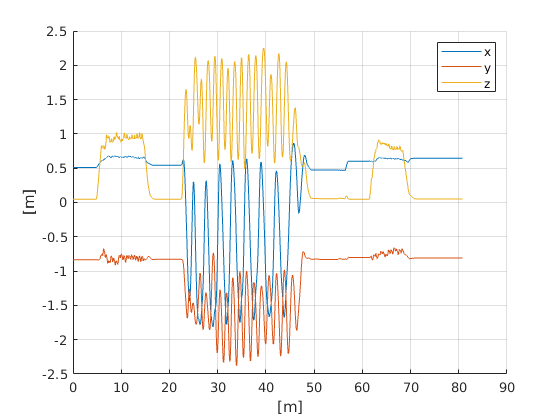

dirs = ["x","y","z"];
figure(); clf; hold on
for i =1:3
    plot(t, p(i,:),"DisplayName",dirs(i))
end

grid on
legend()
xlabel("[m]")
ylabel("[m]")

#### Rig rotation matrix

The rotation matrix is from local to global, that is body to global 

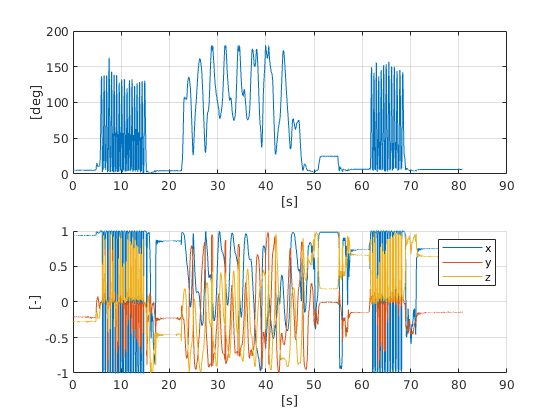

R_nb_rig_tot = squeeze(data_mc.RigidBodies.Rotations); % Rotation matrix
R_nb_rig = R_nb_rig_tot(:,good_points); % Take away nans 
R_nb_rig_3x3 = reshape(R_nb_rig,3,3,[]);
R_bn_rig_3x3 = zeros(size(R_nb_rig_3x3));

for n = 1:size(R_nb_rig_3x3,3)
    R_bn_rig_3x3(:,:,n) = R_nb_rig_3x3(:,:,n)';
end

figure(); hold on
ax = zeros(2,1);

axang = rotm2axang(R_nb_rig_3x3);
ax(1) = subplot(2,1,1);


plot(t, rad2deg(axang(:,4)))
% set(gca, "YScale", "log")
grid on
xlabel("[s]")
ylabel("[deg]")


ax(2) = subplot(2,1,2); hold on
for i = 1:3
    plot(t, axang(:,i))
end
grid on
legend("x","y","z")
xlabel("[s]")
ylabel("[-]")


% linkaxes(ax, "x");

## Estimate angular velocity from MC rotation matrices 

Use a forward differencing scheme.

w_nb_hat =  R2w_central_diff(R_nb_rig_3x3, t)

w_nb_hat =        NaN   -0.0500   -0.0389    0.0817    0.0315   -0.0463    0.0169    0.0389    0.0150   -0.0183   -0.0213   -0.0655   -0.0245    0.0721    0.0019   -0.0642   -0.0257    0.0273    0.0420    0.0218    0.0133    0.0022   -0.0670   -0.0491    0.0230   -0.0014   -0.0204    0.0505    0.0221   -0.0370    0.0322    0.0120   -0.0379   -0.0529    0.0136    0.0709   -0.0361    0.0208   -0.0033   -0.0244    0.0047   -0.0172    0.0544    0.0389    0.0179   -0.0028   -0.0335    0.0200    0.0338   -0.0011
       NaN   -0.0011   -0.0752   -0.0128    0.0223   -0.0498   -0.0010   -0.0091    0.0099    0.0088   -0.0129    0.0045    0.0079    0.0255    0.0068   -0.0186   -0.0070   -0.0071    0.0096    0.0288    0.0103   -0.0382   -0.0294    0.0184    0.0205    0.0096   -0.0036    0.0267    0.0189   -0.0597   -0.0358    0.0343    0.0181   -0.0126    0.0036   -0.0255    0.0025    0.0156   -0.0114    0.0182   -0.0104   -0.0083    0.0231    0.0196    0.0079    0.0039   -0.0292   -0.0030    0.00

% Set the neighbours
w_nb_hat(:,1) = w_nb_hat(:,2);
w_nb_hat(:,end) = w_nb_hat(:,end-1);
% zeros(3,length(t));
% 
% for k = 2:length(t)
%     dt = t(k) - t(k-1);
%     w_nb_hat(:,k) = logSO3(R_nb_rig_3x3(:,:,k-1)'*R_nb_rig_3x3(:,:,k))/dt;
% end


## Rotate IMU to IMU-rig coarse

Found this matrix by looking at the photos.

### Plot angular velocity components

figure()
ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU_mc_frame.time, data_IMU_mc_frame.mean_gyro(i,:), "DisplayName","IMU")
    grid on 
    legend
end
linkaxes(ax, 'x'); clf reset;

Looks like they are the same.

### Plot angular velocity norm

Compare the norm instead, not depedent on the orientation of the rig

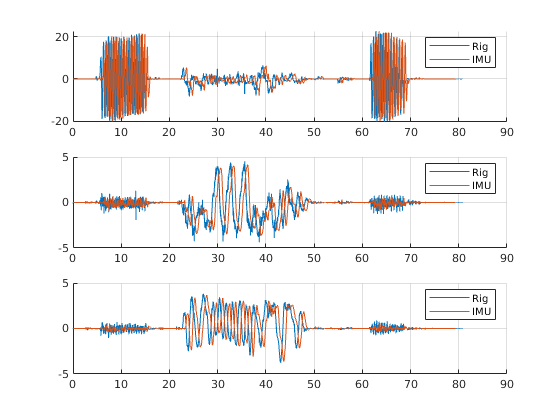

figure()

ax = zeros(3,1);
hold on
plot(t, norm_time(w_nb_hat), "DisplayName","Rig")
plot(data_IMU.time, norm_time(data_IMU_mc_frame.mean_gyro), "DisplayName","IMU")
grid on 
legend

The normed signal of the angular velocity does not look very smooth, that can be explained by the $y$ and $z$ components that are quire noisy. It is then better to just use $x$ component.

## Estimate rotation matrix between IMU and rig using gravity (Fine alignment)

The body frames of the IMU and the rig is not perfectly aligned. 

Downward in bodyframe should point in the direction of gravity in body frame coordinates.

Downward of the navigation frame is the third column of the R_bn matrix, the rotation matrix from navigation frame to body frame.

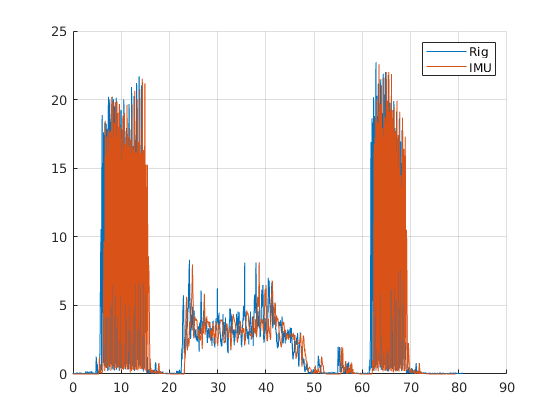

rig_unit_tot = reshape(R_bn_rig_3x3(:,3,:),3,[])
imu_unit_tot = normalize_norm_v(data_IMU_mc_frame.mean_acc)

mask_stationary_rig = t <= 0.5;
mask_stationary_IMU = data_IMU_mc_frame.time <= 4;

figure(); 

rig_unit_tot =     0.0177    0.0178    0.0178    0.0185    0.0179    0.0183    0.0184    0.0183    0.0184    0.0182    0.0184    0.0183    0.0183    0.0182    0.0180    0.0182    0.0182    0.0183    0.0183    0.0181    0.0180    0.0180    0.0184    0.0183    0.0182    0.0181    0.0181    0.0182    0.0179    0.0180    0.0185    0.0183    0.0181    0.0182    0.0182    0.0181    0.0185    0.0181    0.0183    0.0182    0.0182    0.0183    0.0182    0.0181    0.0180    0.0180    0.0180    0.0183    0.0180    0.0182
    0.0857    0.0858    0.0852    0.0854    0.0860    0.0857    0.0855    0.0859    0.0859    0.0861    0.0857    0.0859    0.0851    0.0856    0.0858    0.0856    0.0852    0.0854    0.0854    0.0858    0.0857    0.0859    0.0857    0.0853    0.0852    0.0855    0.0852    0.0853    0.0857    0.0855    0.0853    0.0858    0.0854    0.0854    0.0849    0.0856    0.0856    0.0852    0.0858    0.0852    0.0856    0.0852    0.0854    0.0858    0.0858    0.0860    0.0858    0.0856    

for i = 1:3

imu_unit_tot =    -0.0013   -0.0019   -0.0015   -0.0021   -0.0011   -0.0021   -0.0021   -0.0018   -0.0013   -0.0021   -0.0012   -0.0029   -0.0022   -0.0010   -0.0020   -0.0019   -0.0020   -0.0023   -0.0011   -0.0030   -0.0027   -0.0016   -0.0028   -0.0009   -0.0025   -0.0023   -0.0013   -0.0019   -0.0012   -0.0014   -0.0019   -0.0006   -0.0014   -0.0023   -0.0015   -0.0030   -0.0026   -0.0028   -0.0020   -0.0007   -0.0014   -0.0032   -0.0018   -0.0022   -0.0012   -0.0019   -0.0029   -0.0020   -0.0022   -0.0024
    0.0394    0.0396    0.0395    0.0398    0.0379    0.0395    0.0387    0.0382    0.0397    0.0387    0.0391    0.0382    0.0386    0.0390    0.0390    0.0389    0.0393    0.0387    0.0391    0.0378    0.0390    0.0386    0.0392    0.0392    0.0400    0.0393    0.0388    0.0382    0.0397    0.0393    0.0378    0.0378    0.0384    0.0388    0.0408    0.0385    0.0395    0.0381    0.0386    0.0386    0.0382    0.0390    0.0384    0.0378    0.0385    0.0391    0.0389    0.0385    

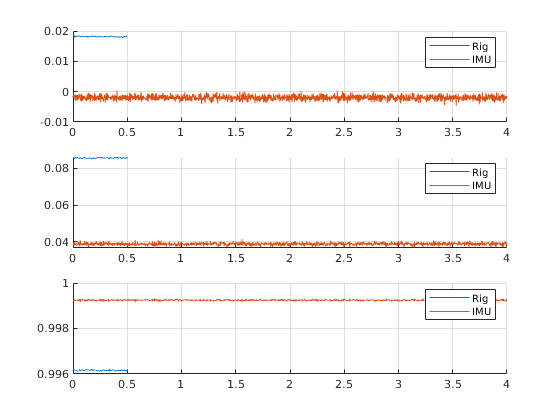

    subplot(3,1,i); hold on 
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot(i,mask_stationary_IMU), "DisplayName","IMU")
    grid on 
    legend
end

### Find angle difference 

[R_stationary_rig_mean, e_R] = average_rotation(R_bn_rig_3x3(:,:,mask_stationary_rig), 100, 1e-12)

1/100: tol: 5.737e-04 / 1.000e-12
2/100: tol: 9.582e-12 / 1.000e-12
3/100: tol: 1.650e-18 / 1.000e-12


R_stationary_rig_mean =     0.9995   -0.0261    0.0181
    0.0244    0.9960    0.0856
   -0.0203   -0.0851    0.9962


e_R = 	1.0e+-3 *

   -0.0680   -0.2019    0.4351    0.1992   -0.3890   -0.1217    0.0867   -0.2943   -0.3067   -0.4472   -0.1203   -0.2285    0.5366    0.0141   -0.1963   -0.0108    0.4525    0.2542    0.1829   -0.1713   -0.0447   -0.3085   -0.0583    0.3715    0.4309    0.1379    0.4440    0.3435   -0.0710    0.1156    0.3157   -0.2026    0.1904    0.1757    0.7195    0.0362    0.0157    0.4022   -0.1966    0.4351    0.0440    0.3946    0.2196   -0.1598   -0.1757   -0.3410   -0.1496    0.0009   -0.3461   -0.3372
   -0.3949   -0.3485   -0.3847    0.3668   -0.2802    0.1493    0.2086    0.1473    0.2820    0.0508    0.2139    0.1849    0.1651    0.0990   -0.0931    0.0143    0.0871    0.1058    0.1720    0.0075   -0.1228   -0.0982    0.2529    0.1889    0.0704   -0.0024   -0.0194    0.0313   -0.2886   -0.1593    0.3046    0.1830   -0.0194    0.0113    0.0805   -0.0345    0.3466   -0.0433    0.1920    0.0572    0.0085    0.1775    0.0936   -0.0595   -0.0986   -0.1367   -0.1437    0.1450 

det(R_stationary_rig_mean)

ans = 1.0000

R_stationary_rig_mean'*R_stationary_rig_mean

ans =     1.0000    0.0000    0.0000
    0.0000    1.0000   -0.0000
    0.0000   -0.0000    1.0000


dir_rig = R_stationary_rig_mean(:,3)

dir_rig =     0.0181
    0.0856
    0.9962


norm(dir_rig)

ans = 1.0000

dir_imu = normalize_norm_v(mean(data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU),2))

dir_imu =    -0.0020
    0.0388
    0.9992



norm(dir_imu)

ans = 1

acosd(dot(dir_rig,dir_imu))

ans = 2.9246

3 degress difference. Level spirit sensitivity is 10mm/m

atand(10e-3/1)

ans = 0.5729

Which is 0.5 deg. Meaning the difference is above what the level spirit can measure. 

Rotationmatrix between unit vectors, from 

R_rig_coarse2rig_fine = rotationMatrixFromTwoUnitVectors(dir_imu, dir_rig)

R_rig_coarse2rig_fine =     0.9998    0.0004    0.0201
   -0.0013    0.9989    0.0469
   -0.0201   -0.0469    0.9987


It is almost the identiy matrix

rad2deg(my_rotm2eul(R_rig_coarse2rig_fine))

ans =    -2.6884
    1.1506
   -0.0771



det(R_rig_coarse2rig_fine)

ans = 1

R_rig_coarse2rig_fine'*R_rig_coarse2rig_fine

ans =     1.0000   -0.0000         0
   -0.0000    1.0000   -0.0000
         0   -0.0000    1.0000


R_rig_coarse2rig_fine*dir_imu

ans =     0.0181
    0.0856
    0.9962


dir_rig

dir_rig =     0.0181
    0.0856
    0.9962


norm(R_rig_coarse2rig_fine*dir_imu - dir_rig)

ans = 2.6961e-08

How many degress does the rotation matrix rotate.

rad2deg(norm(logSO3(R_rig_coarse2rig_fine)))

ans = 2.9246

Check that the rotation matrix is reasonable 

imu_unit_tot_2 = normalize_norm_v(R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_acc(:,mask_stationary_IMU))

imu_unit_tot_2 =     0.0188    0.0182    0.0186    0.0180    0.0191    0.0180    0.0180    0.0183    0.0189    0.0181    0.0190    0.0172    0.0179    0.0192    0.0181    0.0182    0.0181    0.0179    0.0190    0.0171    0.0175    0.0185    0.0173    0.0192    0.0176    0.0178    0.0189    0.0182    0.0189    0.0188    0.0183    0.0195    0.0187    0.0178    0.0186    0.0171    0.0175    0.0174    0.0181    0.0194    0.0188    0.0169    0.0183    0.0180    0.0189    0.0183    0.0172    0.0181    0.0179    0.0177
    0.0862    0.0864    0.0863    0.0866    0.0847    0.0863    0.0855    0.0850    0.0865    0.0855    0.0859    0.0850    0.0854    0.0858    0.0858    0.0857    0.0861    0.0855    0.0859    0.0846    0.0858    0.0854    0.0860    0.0860    0.0868    0.0861    0.0856    0.0850    0.0865    0.0861    0.0846    0.0846    0.0852    0.0856    0.0876    0.0853    0.0863    0.0849    0.0854    0.0854    0.0850    0.0858    0.0852    0.0846    0.0853    0.0859    0.0857    0.0853  

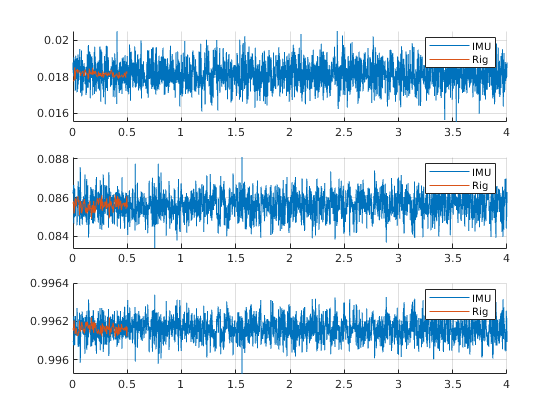

figure(); 
for i = 1:3
    subplot(3,1,i); hold on 
    
    plot(data_IMU.time(mask_stationary_IMU), imu_unit_tot_2(i,mask_stationary_IMU), "DisplayName","IMU")
    plot(t(mask_stationary_rig), rig_unit_tot(i,mask_stationary_rig), "DisplayName","Rig")
    grid on 
    legend
end

Check that gyro gives reasonable reasults as well

phase_roll_1 = data_IMU.start_and_stop(1,2):data_IMU.start_and_stop(2,1);

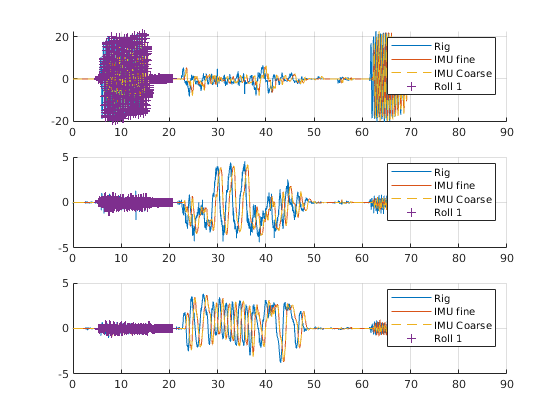

gyro_2 = R_rig_coarse2rig_fine*data_IMU_mc_frame.mean_gyro;
figure()
ax = zeros(3,1);

for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t, w_nb_hat(i,:), "DisplayName","Rig")
    plot(data_IMU.time, gyro_2(i,:) , "DisplayName","IMU fine ")
    plot(data_IMU.time, data_IMU_mc_frame.mean_gyro(i,:) ,"--", "DisplayName","IMU Coarse")
    plot(data_IMU.time(phase_roll_1), data_IMU_mc_frame.mean_gyro(i,phase_roll_1) ,"+", "DisplayName","Roll 1", "MarkerIndices",1:10:length(phase_roll_1))
    grid on 
    legend
end

The fine rotation does not matter.

#### Rotatate measurements fine alignment

## Grid search time sync

Extract the phase time sync sequence

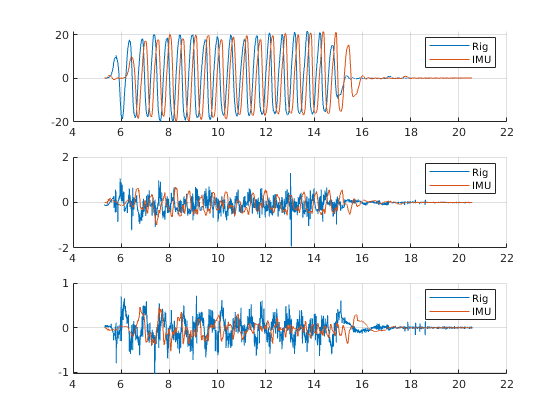


figure
ax = zeros(3,1);
time_IMU = data_IMU.time(phase_roll_1);
mask_time_rig = logical( (t >= time_IMU(1)) .* (t <= time_IMU(end)));
for i = 1:3
    ax(i) = subplot(3,1,i); hold on
    plot(t(mask_time_rig), w_nb_hat(i,mask_time_rig), "DisplayName","Rig")
    plot(time_IMU, data_IMU_mc_frame.mean_gyro(i,phase_roll_1), "DisplayName","IMU")
    grid on 
    legend
end
slice_time_sync_1_phase = phase_roll_1
% linkaxes(ax);

Interpolate rig w to IMU angular velocity. Use the x direction.

y_interp = data_IMU_mc_frame.mean_gyro(1,slice_time_sync_1_phase);

slice_time_sync_1_phase =         2655        2656        2657        2658        2659        2660        2661        2662        2663        2664        2665        2666        2667        2668        2669        2670        2671        2672        2673        2674        2675        2676        2677        2678        2679        2680        2681        2682        2683        2684        2685        2686        2687        2688        2689        2690        2691        2692        2693        2694        2695        2696        2697        2698        2699        2700        2701        2702        2703        2704


t_interp = time_IMU;
length(t_interp)

% cubic spline iterpolation 
f = @(t_shift) interp1( t, w_nb_hat(1,:),  t_interp - t_shift, 'pchip');
f(0)

cost = @(t_shift) sum((y_interp - f(t_shift)).^2);

ans = 7621

cost(0)

Ocular inspection of coarse time shift 

t_shift_coarse = 0.5


ans =    -0.0712   -0.0706   -0.0710   -0.0759   -0.0798   -0.0670   -0.0410   -0.0337   -0.0344   -0.0358   -0.0627   -0.1143   -0.1239   -0.0829   -0.0491   -0.0477   -0.0474   -0.0494   -0.0675   -0.0823   -0.0728   -0.0532   -0.0508   -0.0771   -0.0986   -0.0982   -0.0954   -0.0874   -0.0515   -0.0235   -0.0284   -0.0439   -0.0655   -0.1075   -0.1366   -0.1226   -0.0866   -0.0532   -0.0166    0.0054   -0.0056   -0.0326   -0.0544   -0.0745   -0.0859   -0.0732   -0.0460   -0.0351   -0.0328   -0.0305


grid_search = t_shift_coarse + (-1:0.01:1);
cost_grid = arrayfun(cost, grid_search);


ans = 1.6865e+06

options = optimset('Display','iter','TolX', 1e-12);
t_shift_opt = fminbnd(cost,grid_search(1),grid_search(end),options);


t_shift_coarse = 0.5000

data_IMU.time_shifted = data_IMU.time - t_shift_opt;
figure(); clf;
plot(grid_search, cost_grid, "-x")
hold on 
yLim = ylim;
plot(t_shift_opt*ones(1,2), yLim, "-r")

 
 Func-count     x          f(x)         Procedure
    1       0.263932  1.72469e+06        initial
    2       0.736068       707130        golden
    3        1.02786  2.17857e+06        golden
    4       0.614369       249678        parabolic
    5       0.563853       998938        parabolic
    6       0.657809      265.657        parabolic
    7       0.659737      376.172        parabolic
    8       0.658549      190.124        parabolic
    9       0.658559      190.111        parabolic
   10       0.658558      190.111        parabolic
   11       0.658558      190.111        parabolic
   12       0.658558      190.111        parabolic
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-12 



ylim(yLim);

### Ensure time shift is ok

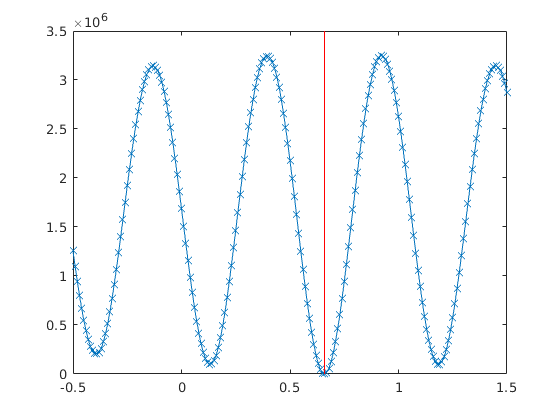

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;
    plot(t, rad2deg(w_nb_hat(i,:))', 'DisplayName', "MC")


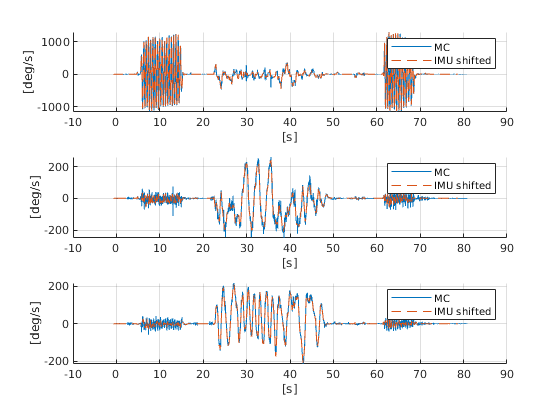

    % plot(data_IMU.time, rad2deg(data_IMU_gyro.gyro_wls_wo_bias_rig_frame_fine(i,:)),'DisplayName','IMU')
    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"--",'DisplayName','IMU shifted')
    
    % yLim = ylim; 
    % X = [data_IMU.start_and_stop(1,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(2,1) data_IMU.start_and_stop(1,1)];
    % Y = [yLim(2) yLim(2) yLim(1) yLim(1)];
    % fill(data_IMU.time_stamp_corr(X), Y, "b", "FaceAlpha", 0.2);
    % ylim(yLim);
    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
end

figure(); hold on 
plot(data_IMU.time_shifted, "DisplayName","Shifted time")
plot(data_IMU.time,"--", "DisplayName","Original Time")
plot(t, "DisplayName","Rig Time")
legend
grid on 


xlim([0 391])
% ylim([-1.35 0.71])

## Find release times

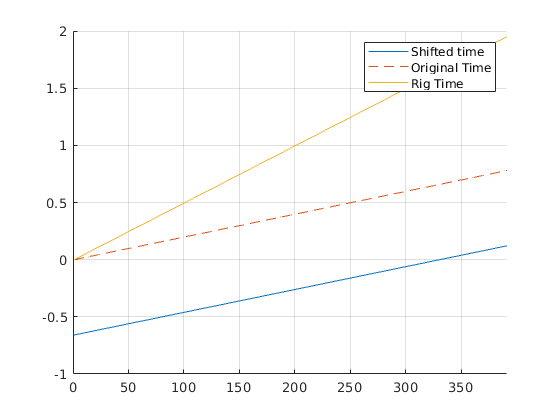



release_times_roll_2 = 61.5 + (0:19)*0.1
release_times_roll_2_end = release_times_roll_2 + 5;

w_roll_2_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2)';
w_roll_2_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_roll_2_end)';



release_times_middle = 22.5 + (0:19)*1.1
release_times_middle_end = release_times_middle + 5;

w_middle_start = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle)';

release_times_roll_2 =    61.5000   61.6000   61.7000   61.8000   61.9000   62.0000   62.1000   62.2000   62.3000   62.4000   62.5000   62.6000   62.7000   62.8000   62.9000   63.0000   63.1000   63.2000   63.3000   63.4000


w_middle_end = interp1(data_IMU.time_shifted, data_IMU_mc_frame.mean_gyro', release_times_middle_end)';

figure(); hold on 

ax = zeros(3,1);
for i = 1:3
    ax(i) = subplot(3,1,i); hold on;

release_times_middle =    22.5000   23.6000   24.7000   25.8000   26.9000   28.0000   29.1000   30.2000   31.3000   32.4000   33.5000   34.6000   35.7000   36.8000   37.9000   39.0000   40.1000   41.2000   42.3000   43.4000


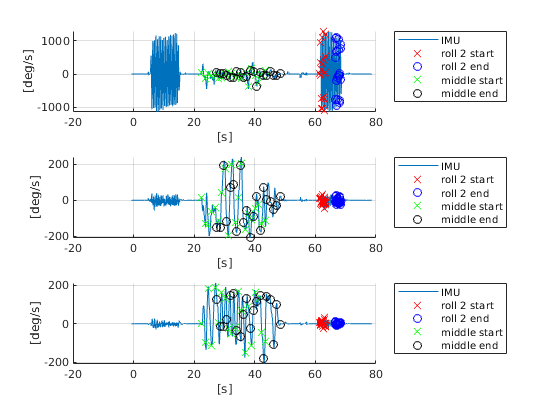


    plot(data_IMU.time_shifted, rad2deg(data_IMU_mc_frame.mean_gyro(i,:)),"-",'DisplayName','IMU')
    plot(release_times_roll_2, rad2deg(w_roll_2_start(i,:)),"rx",'DisplayName','roll 2 start')
    plot(release_times_roll_2_end, rad2deg(w_roll_2_end(i,:)),"bo",'DisplayName','roll 2 end')
    
    plot(release_times_middle, rad2deg(w_middle_start(i,:)),"gx",'DisplayName','middle start')
    plot(release_times_middle_end, rad2deg(w_middle_end(i,:)),"ko",'DisplayName','middle end')

    grid on 
    legend

    xlabel("[s]")
    ylabel("[deg/s]")
    legend("Location","bestoutside")
end

## Save Joint data

% mkdir(fullfile(pathScript,"estimated_parameters"))
save(fullfile(pathScript,"estimated_parameters","R0_and_tshift_v2.mat"), "R_imu2rig_coarse","t_shift_opt", "release_times_middle", "release_times_roll_2");

% save(fullfile(pathScript,"data_processed","data_initial_values.mat"),"-struct", "data_initial_values");

## Conclusions 

- Coarse alignment is only off by 3 degrees.

- The time-sync was performed on the fine aligned gyroscope wls data, but it is expected that this does not matter if the time-shift estimation was done on the coarse aligned data.

- The time-shift was estimation was done using linearly interpolated data and grid-search. 